
%
%   This design does not meet my capabilities, 
%
%
%
%
%
%



die=dielectric('Taconic RF-35')

die =   dielectric with properties:

           Name: 'Taconic RF-35'
       EpsilonR: 3.5000
    LossTangent: 0.0018
      Thickness: 0.0060

For more materials see catalog


p2 = patchMicrostripInsetfed('Substrate', die)

p2 =   patchMicrostripInsetfed with properties:

               Length: 0.0300
                Width: 0.0290
               Height: 0.0013
            Substrate: [1×1 dielectric]
    PatchCenterOffset: [0 0]
           FeedOffset: [-0.0300 0]
       StripLineWidth: 1.0000e-03
          NotchLength: 0.0080
           NotchWidth: 0.0030
    GroundPlaneLength: 0.0600
     GroundPlaneWidth: 0.0600
                 Tilt: 0
             TiltAxis: [1 0 0]
                 Load: [1×1 lumpedElement]



Z = impedance(p2,2.4e9)

Z = 8.0672e+00 - 1.7444e+02i

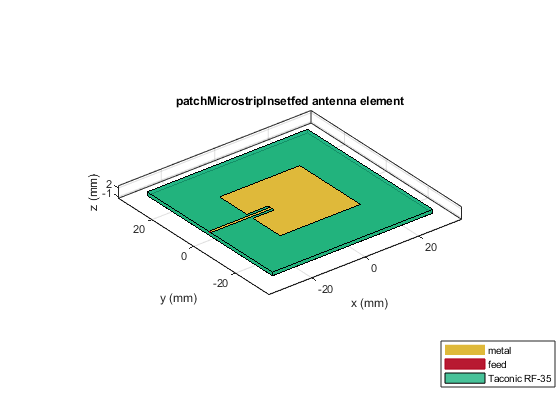



show(p2)

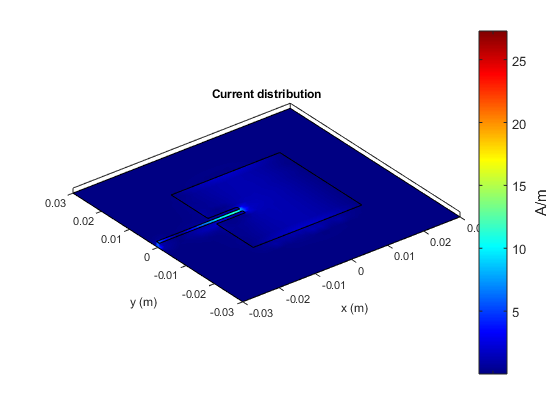

current(p2,2.4e9)

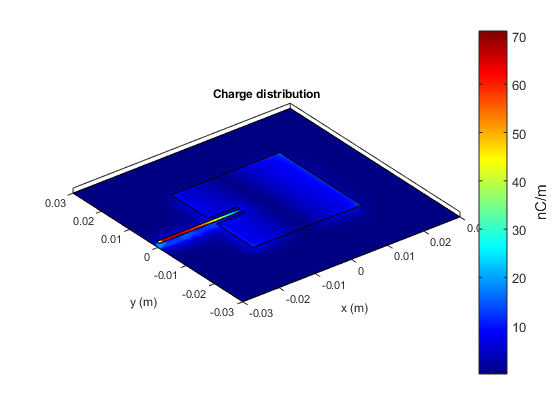

charge(p2, 2.4e9)

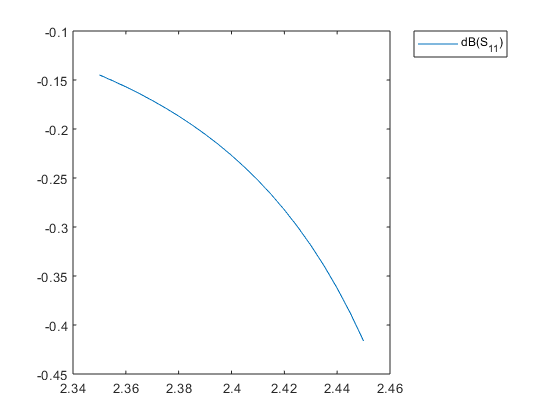

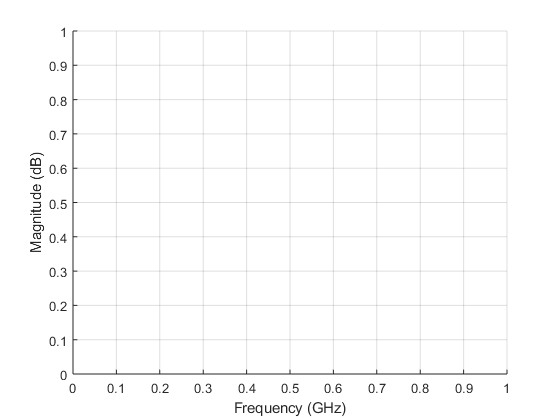

pattern(p2, 2.4e9)
freq = linspace(2.35e9,2.45e9,21);
s2 = sparameters(p2,freq,50); 
rfplot(s2)